
pd = 0.9;            % Probability of detection

pfa = 1e-6;          % Probability of false alarm

MaxRange = 10e3;     % Maximum unambiguous range

res = 10;            % Required range resolution

rcs = 1;             % Radar Cross Section

NumPulses= 10;       % Number of Pulses per cycle

prf = 2e3;           % Pulse Repetition Frequency

fc = 10e9;           % Operating Frequency

txGain= 20;          % Transmitter Gain

arraySize=[5 5];     %Size of the Phased Array Antenna

pd = 0.9;            % Probability of detection
pfa = 1e-6;          % Probability of false alarm
max_range = 5000;    % Maximum unambiguous range
range_res = 20;      % Required range resolution
tgt_rcs = 1;         % Required target radar cross section
fc = 5e9;


%% Monostatic Radar System Design

prop_speed = 3e8;   % Propagation speed
pulse_bw = prop_speed/(2*range_res);    % Pulse bandwidth
pulse_width = 1/pulse_bw;               % Pulse width
prf = prop_speed/(2*max_range);         % Pulse repetition frequency
fs = 2*pulse_bw; 



## Monostatic Radar System Design



prop_speed = 3e8;    % Propagartion Speed        
c= prop_speed;  
pulseWidth = 100e-6; %Pulse Width (for Rectangular waveform)
pulseBw = 1/pulseWidth;        
lambda= c/fc;

%Waveform Model
waveform= phased.LinearFMWaveform('SampleRate',fs, ...
    'PRF',prf,'OutputFormat','Pulses','NumPulses',1,'SweepBandwidth',fs/2, ...
    'DurationSpecification','Duty cycle','DutyCycle',0.017);


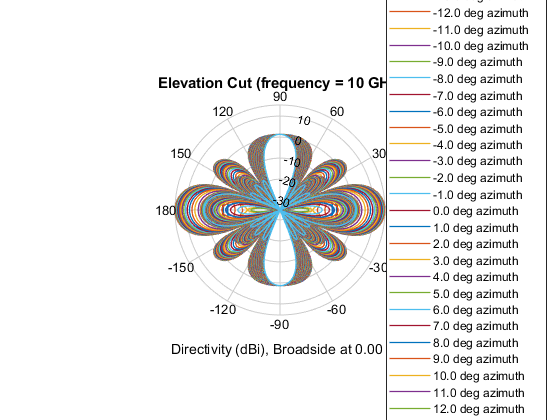


ant = phased.IsotropicAntennaElement(...
    'FrequencyRange',[5e9 50e10]);

antenna= phased.URA('Size', 5,'ElementSpacing', lambda/2, 'Element',ant);
antennaPos= getElementPosition(antenna);
posRec= antennaPos(2:3,:);

axis([-1.5 1.5 -2 2]);
xlabel("x");
ylabel("y");

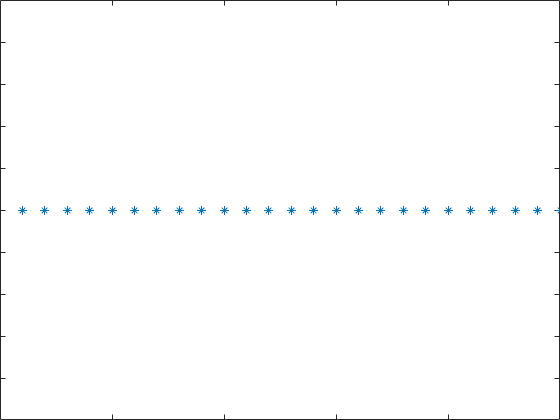

plot(antennaPos(1,:), 'LineStyle',"none", "Marker","*");


% 

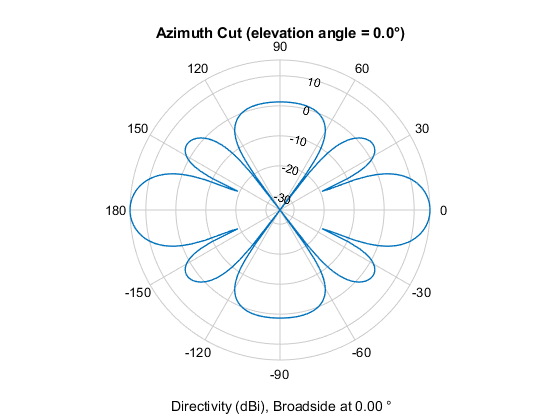

figure("GraphicsSmoothing","on");
patternAzimuth(antenna, fc, 0);

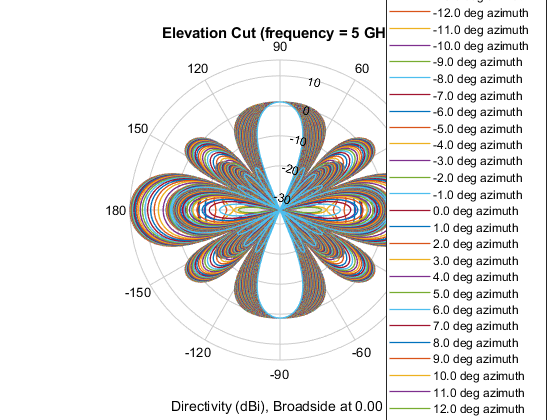

figure;
patternElevation(antenna, fc, [-90:90]);

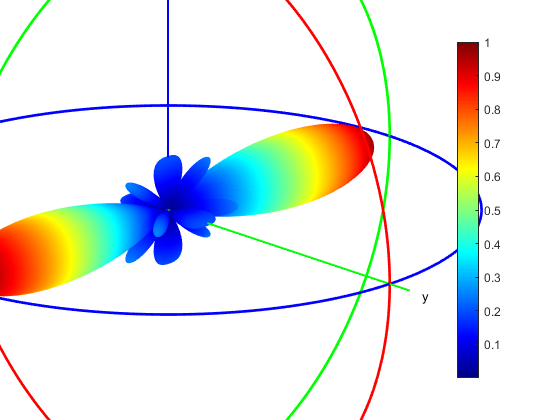

a= phased.URA([5 5], lambda/2);
[ef, az, el]= pattern(a, fc, 'Type','efield');

phi= az';
theta= (90-el);
mag= ef';
figure;
patternCustom(mag, theta, phi);
view(50,20);
ax = gca;
ax.Position = [-0.15 0.1 0.9 0.8];
camva(4.5);
campos([10 10 5]);
title("3-D Radiation Pattern")



%  antenna= phased.IsotropicAntennaElement("FrequencyRange", [5e9 15e9]);

angle= [0; 0];

response= antenna(fc, angle);


% patternAzimuth(antenna, fc, [-90:90]);

% patternElevation(antenna, fc, [-180:180]);


antennaPlatform= phased.Platform('InitialPosition', [0; 0; 0], 'Velocity',[0; 0; 0], 'ScanMode',"Circular");

tgtPos = [1500; -400; 2000]

tgtPos =         1500
        -400
        2000


tgtVel =  [0; 0; 0];
targetPlatform= phased.Platform('InitialPosition', tgtPos, 'Velocity', tgtVel );
tgtRcs= 15;
target= phased.RadarTarget("Model", "Nonfluctuating", "MeanRCS", tgtRcs,"PropagationSpeed", c, "OperatingFrequency", fc);


[tgtRange, tgtAngle]= rangeangle(targetPlatform.InitialPosition, antennaPlatform.InitialPosition)

tgtRange = 2.5318e+03

tgtAngle =   -14.9314
   52.1811


SNR= albersheim(pd, pfa, NumPulses)

SNR = 4.9904


peakPower= radareqpow(lambda,MaxRange,SNR,pulseWidth,...
    'RCS',tgtRcs,'Gain',txGain)

peakPower = 4.6425

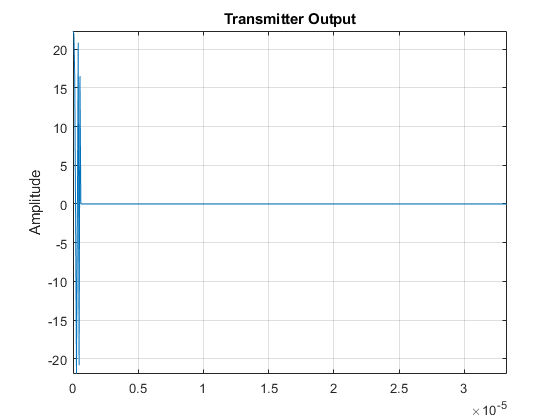

transmitter= phased.Transmitter("PeakPower", ceil(peakPower), ...
    'Gain',txGain, ...
    'InUseOutputPort', true, ...
    'CoherentOnTransmit', true);

wf=waveform();
[txOutput,txStatus] = transmitter(wf);

t = unigrid(0,1/waveform.SampleRate,1/waveform.PRF,'[)');
plot(t,real(txOutput))
axis tight
grid on
ylabel('Amplitude')
title('Transmitter Output')

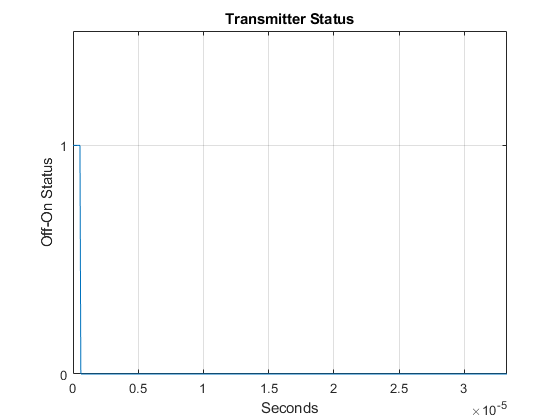

plot(t,txStatus)
axis([0 t(end) 0 1.5])
xlabel('Seconds')
grid on
ylabel('Off-On Status')
set(gca,'ytick',[0 1])
title('Transmitter Status')

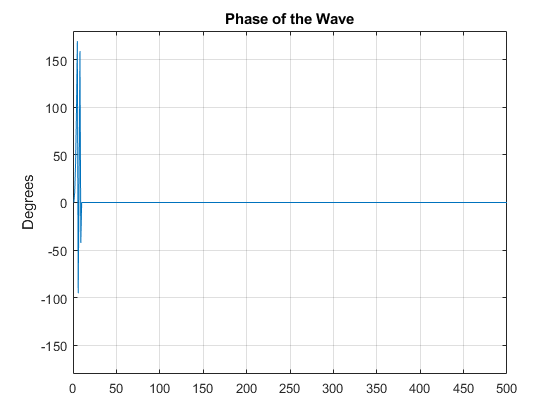


plot(rad2deg(atan2(imag(txOutput), real(txOutput))));
axis([0 length(wf) -180 180]);
ylabel('Degrees')
title('Phase of the Wave');
grid on;